T = readmatrix('exp1_static_force_angle.xlsx')

T =        NaN    0.3900    0.3300    0.1200         0    0.1200    0.1100    0.2800
       NaN   -0.6500   -0.2500   -0.1000         0    0.0500   -0.1300   -0.3800
       NaN    0.7000         0   -0.2200         0   -0.0600    0.2100    0.4800
       NaN   -1.0000   -0.0900    0.0200         0   -0.3000   -0.9600   -1.7000
       NaN   -0.1200   -0.0700    0.0400         0   -0.0700   -0.1700   -0.6900
       NaN    4.6000    3.0500    1.7000         0   -2.1200   -3.8200   -4.8000
       NaN   -5.2000   -0.2000    0.0200         0   -0.1200   -1.3200   -5.4000
       NaN   -0.5000   -0.5400   -0.1900         0   -0.1600   -0.3000   -0.4000
       NaN   11.7000    5.8000    3.0200         0   -4.1200   -7.5200  -12.2000
       NaN  -13.1600   -1.5000   -0.2000         0   -0.4400   -4.2000  -11.4500


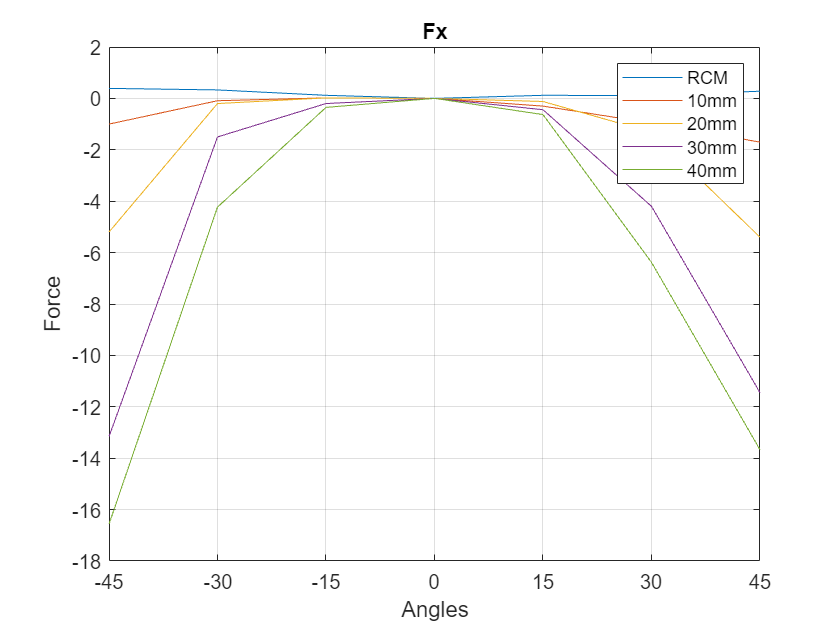

clf;
plot(T(1,2:end))
hold on;
plot(T(4,2:end));
plot(T(7,2:end));
plot(T(10,2:end));
plot(T(13,2:end));

title('Fx')
xlabel('Angles');
ylabel('Force');
legend('RCM', '10mm', '20mm', '30mm', '40mm');

% Set the x-axis ticks to match the desired angles
xticks(1:7); % Assuming the data has 7 points
xticklabels({'-45', '-30', '-15', '0', '15', '30', '45'});
grid on;

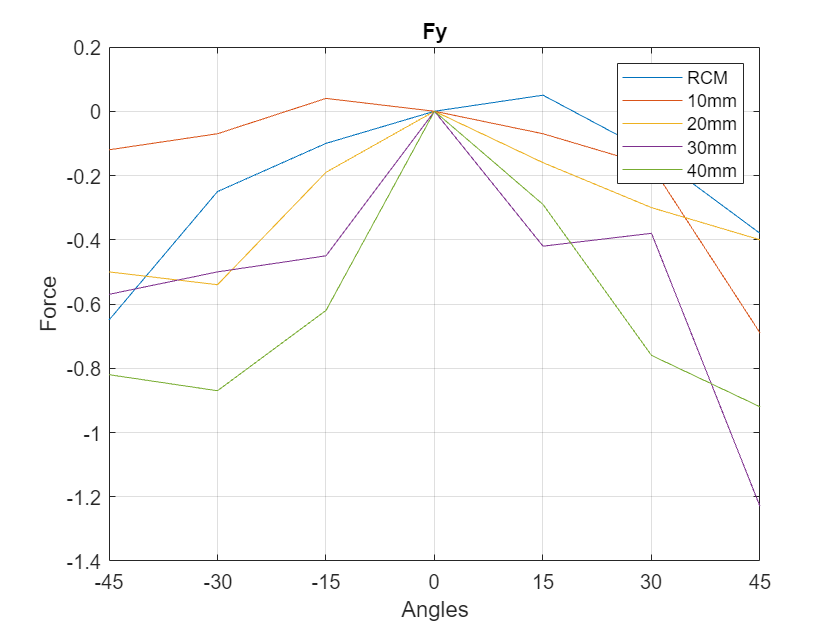

clf;
plot(T(2,2:end))
hold on;
plot(T(5,2:end));
plot(T(8,2:end));
plot(T(11,2:end));
plot(T(14,2:end));

title('Fy')
xlabel('Angles');
ylabel('Force');
legend('RCM', '10mm', '20mm', '30mm', '40mm');

% Set the x-axis ticks to match the desired angles
xticks(1:7); % Assuming the data has 7 points
xticklabels({'-45', '-30', '-15', '0', '15', '30', '45'});
grid on;

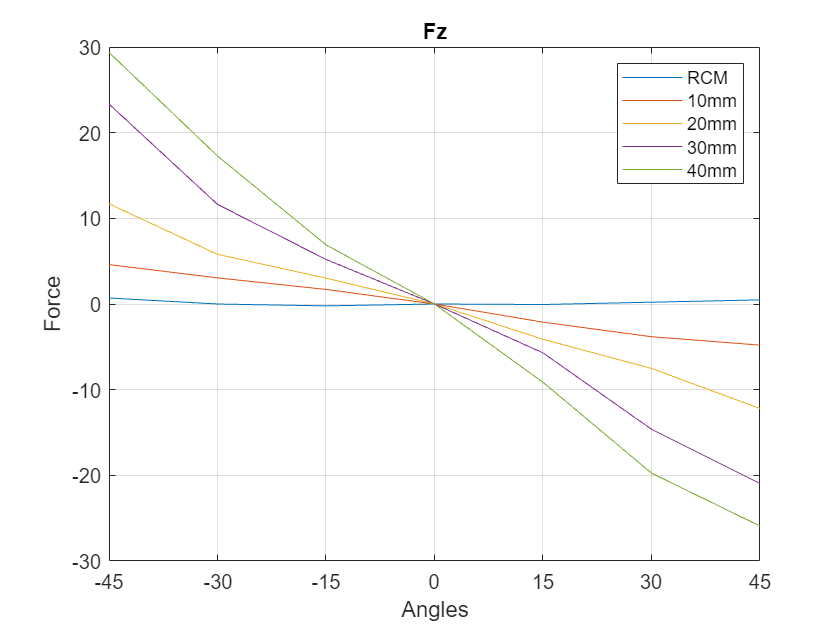

clf;
plot(T(3,2:end))
hold on;
plot(T(6,2:end));
plot(T(9,2:end));
plot(T(12,2:end));
plot(T(15,2:end));

title('Fz')
xlabel('Angles');
ylabel('Force');
legend('RCM', '10mm', '20mm', '30mm', '40mm');

% Set the x-axis ticks to match the desired angles
xticks(1:7); % Assuming the data has 7 points
xticklabels({'-45', '-30', '-15', '0', '15', '30', '45'});
grid on;

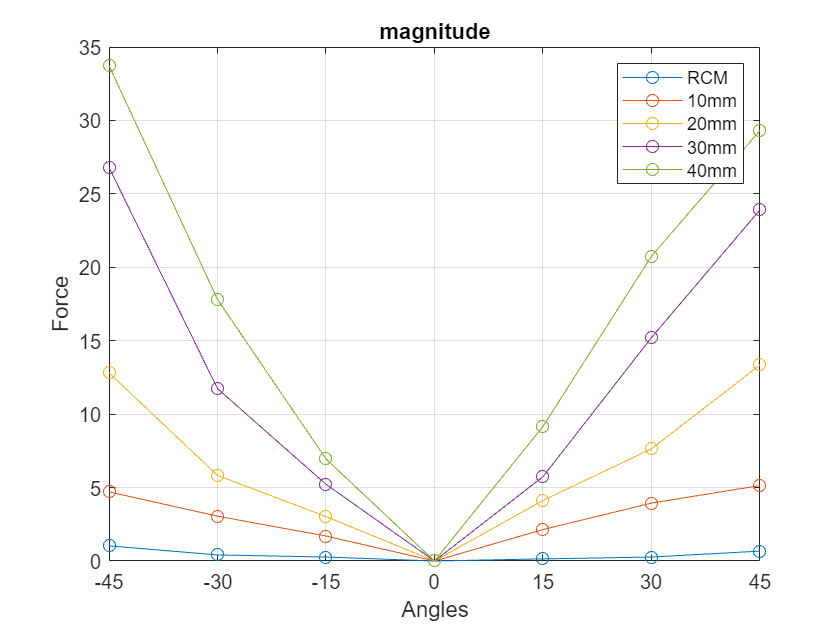

clf;
x1 = T(1, 2:end);
y1 = T(2, 2:end);
z1 = T(3, 2:end);
x2 = T(4, 2:end);
y2 = T(5, 2:end);
z2 = T(6, 2:end);
x3 = T(7, 2:end);
y3 = T(8, 2:end);
z3 = T(9, 2:end);
x4 = T(10, 2:end);
y4 = T(11, 2:end);
z4 = T(12, 2:end);
x5 = T(13, 2:end);
y5 = T(14, 2:end);
z5 = T(15, 2:end);

% Calculate the magnitude of the vector (x^2 + y^2 + z^2)^(1/2)
magnitude1 = sqrt(x1.^2 + y1.^2 + z1.^2);
magnitude2 = sqrt(x2.^2 + y2.^2 + z2.^2);
magnitude3 = sqrt(x3.^2 + y3.^2 + z3.^2);
magnitude4 = sqrt(x4.^2 + y4.^2 + z4.^2);
magnitude5 = sqrt(x5.^2 + y5.^2 + z5.^2);

plot(magnitude1,'-o');
hold on;
plot(magnitude2,'-o');
plot(magnitude3,'-o');
plot(magnitude4,'-o');
plot(magnitude5,'-o');

% Plot the result
title('magnitude')
xlabel('Angles');
ylabel('Force');
legend('RCM', '10mm', '20mm', '30mm', '40mm');

% Set the x-axis ticks to match the desired angles
xticks(1:7); % Assuming the data has 7 points
xticklabels({'-45', '-30', '-15', '0', '15', '30', '45'});
grid on;